# #########################################################################

# #########################################################################

# These are the thresholded indiviudally smoothed images with t>0 in the conjunction map.

# #########################################################################

# #########################################################################

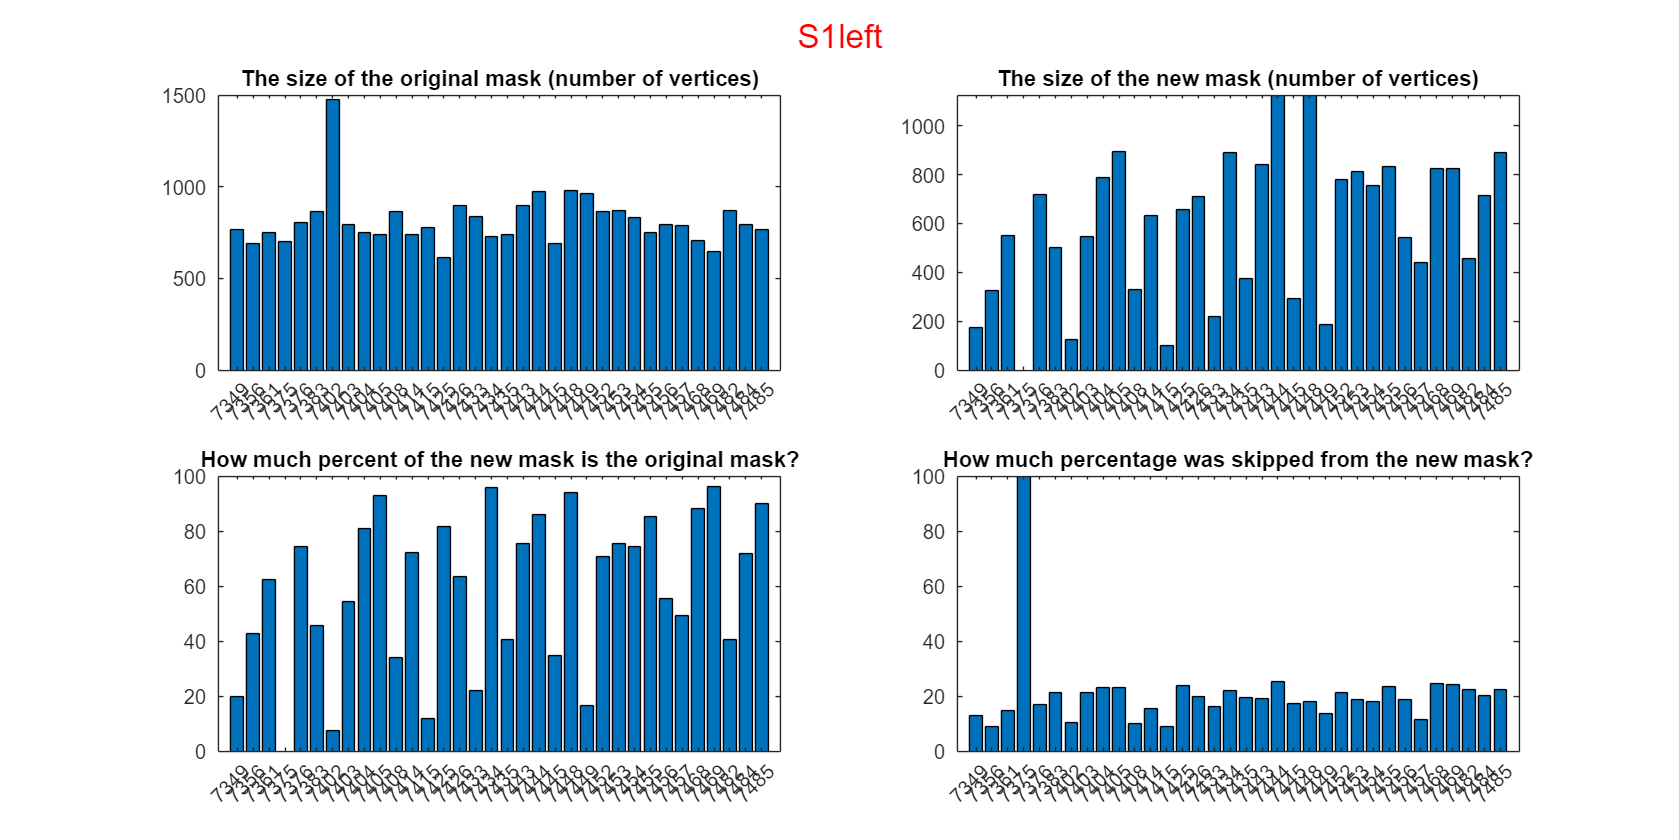


[originalmasksize,newmasksize,percentoforiginalmask,percentofskippedverticesfromnew,subjid]=plotroi('S1','left');

mean(percentoforiginalmask)

ans = 59.0947

display('Note that subject 7375 does not have activation in the area in question for S1\n and subject 7376 show some activation because it has only noise...(see orig image)')

Note that subject 7375 does not have activation in the area in question for S1\n and subject 7376 show some activation because it has only noise...(see orig image)


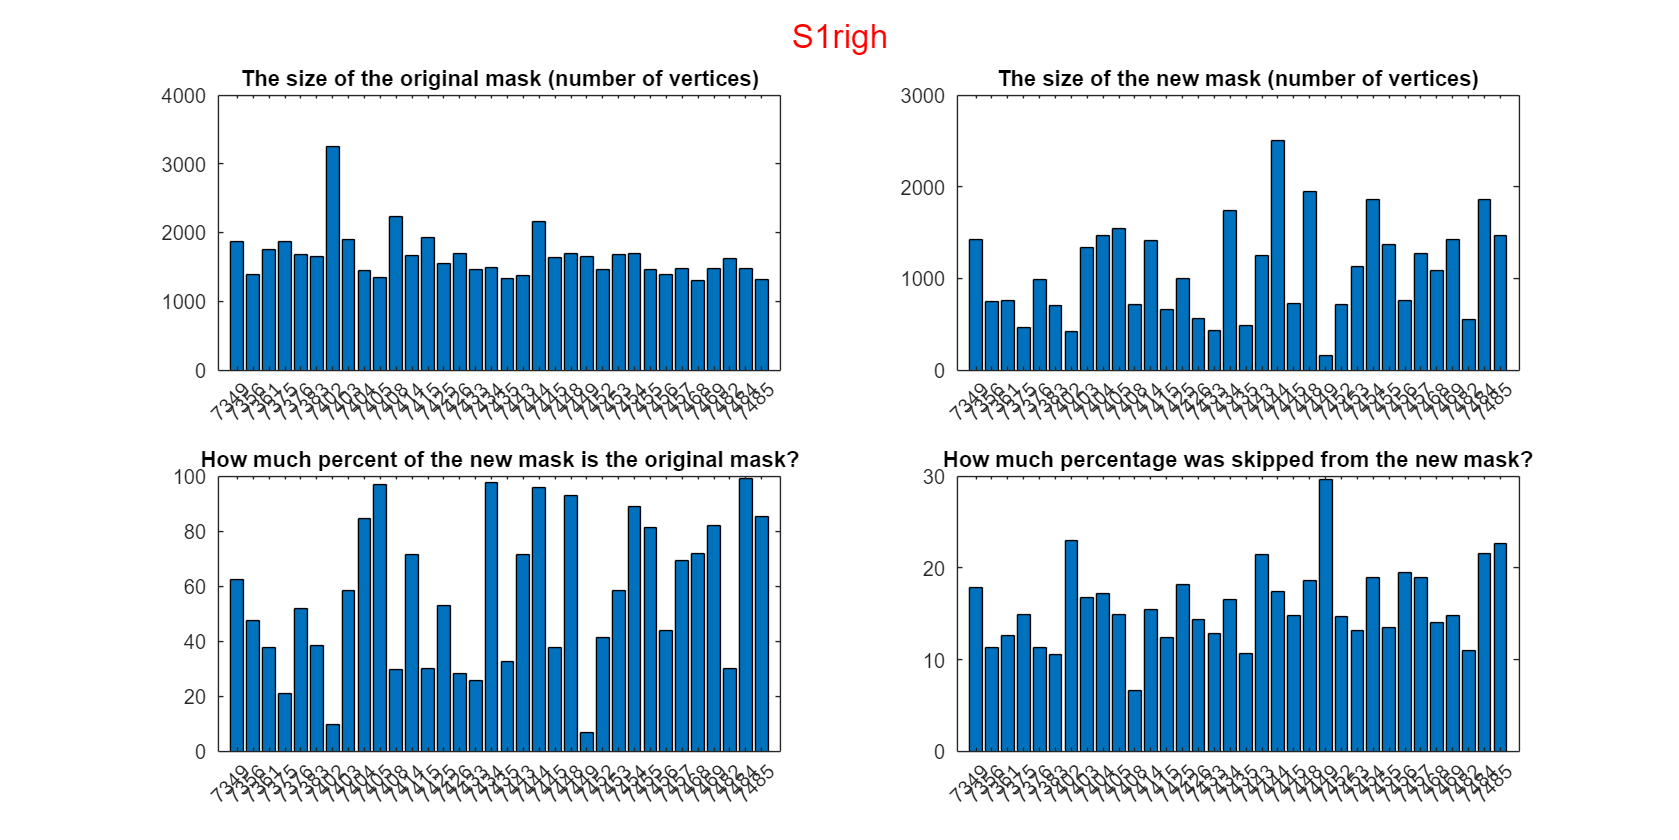

[originalmasksize,newmasksize,percentoforiginalmask,percentofskippedverticesfromnew,subjid]=plotroi('S1','righ');

mean(percentoforiginalmask)

ans = 56.9212

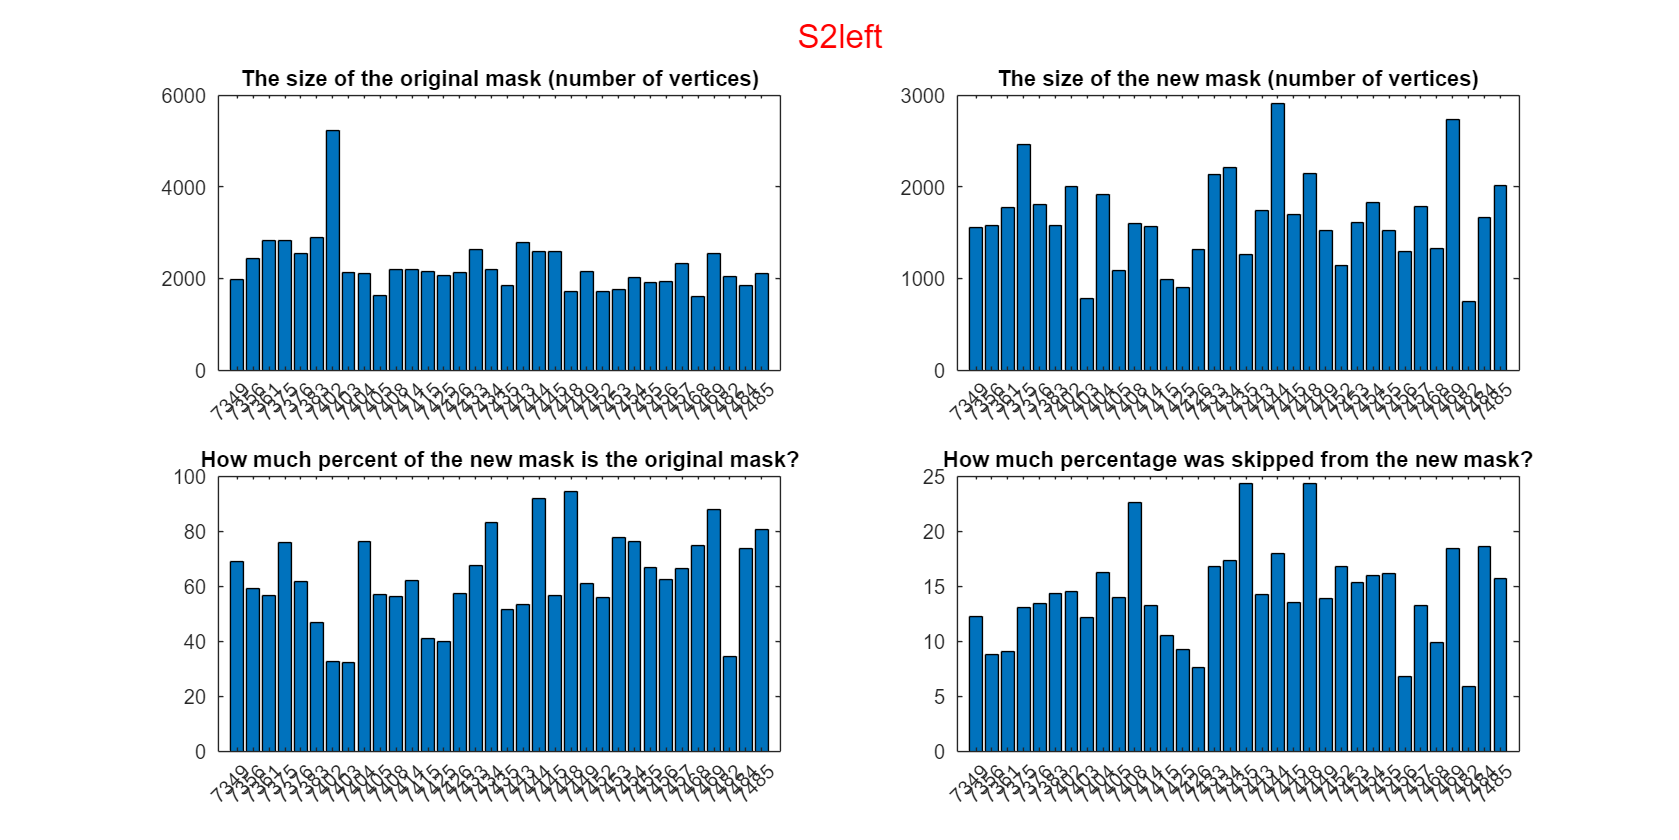

[originalmasksize,newmasksize,percentoforiginalmask,percentofskippedverticesfromnew,subjid]=plotroi('S2','left');

mean(percentoforiginalmask)

ans = 62.9624

mean(percentoforiginalmask)

ans = 62.9624

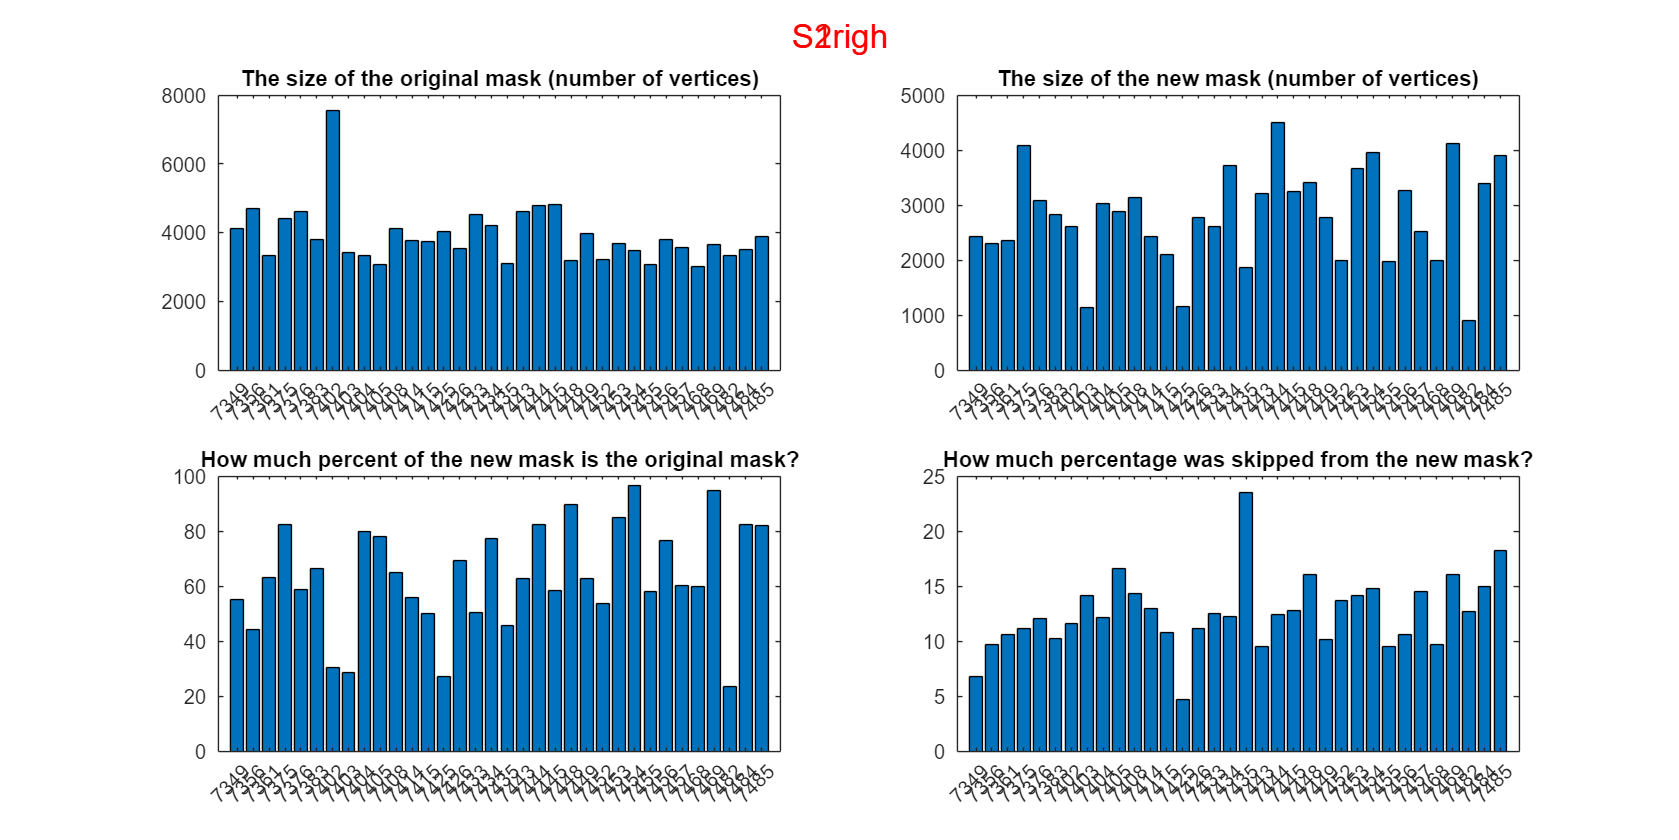

[originalmasksize,newmasksize,percentoforiginalmask,percentofskippedverticesfromnew,subjid]=plotroi('S2','righ');

mean(percentoforiginalmask)

ans = 63.4753

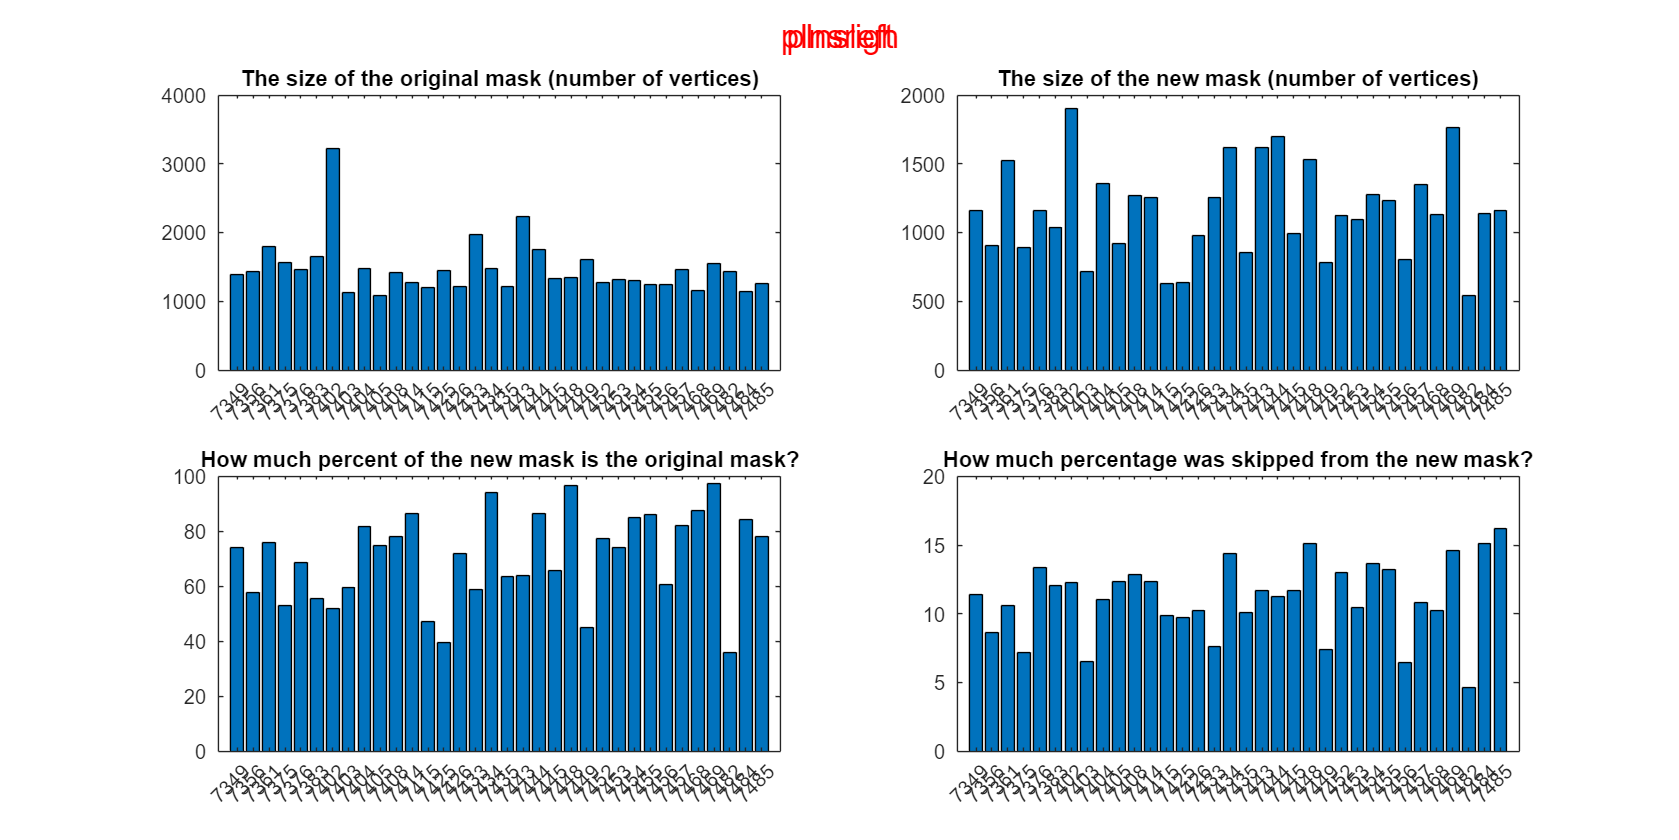

[originalmasksize,newmasksize,percentoforiginalmask,percentofskippedverticesfromnew,subjid]=plotroi('pIns','left');

mean(percentoforiginalmask)

ans = 70.5624

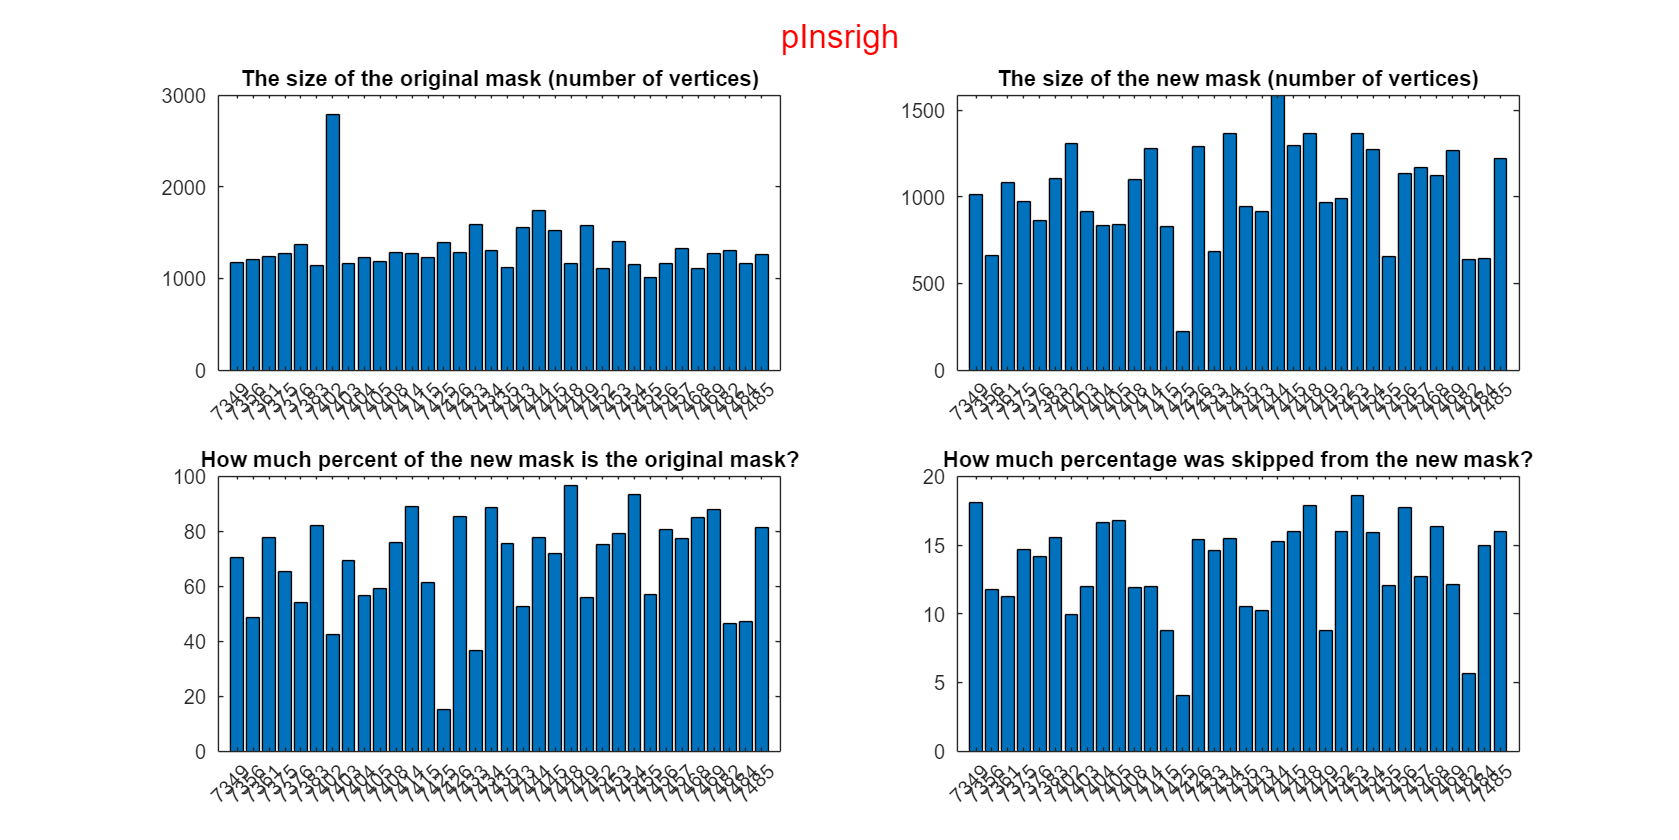


[originalmasksize,newmasksize,percentoforiginalmask,percentofskippedverticesfromnew,subjid]=plotroi('pIns','righ');

mean(percentoforiginalmask)

ans = 68.2126

# #########################################################################

# #########################################################################

# **These are the thresholded indiviudally smoothed images with t>1 in the conjunction map.**

# #########################################################################

# #########################################################################

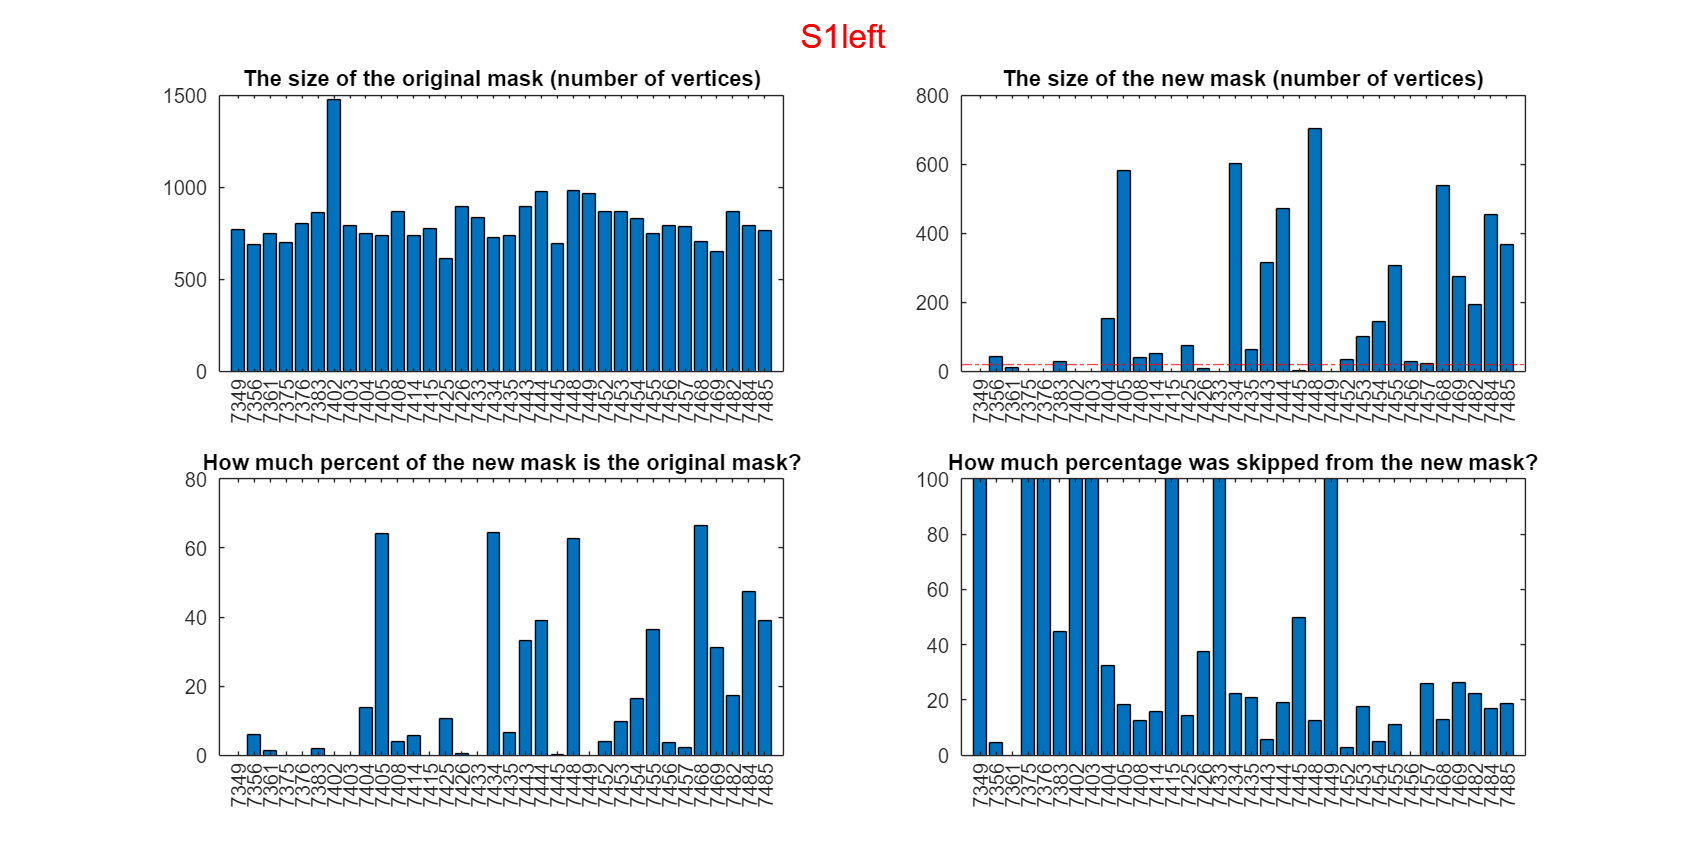

[~,~,percentoforiginalmask,~,~]=plotroi('S1','left');

mean(percentoforiginalmask)

ans = 17.2921

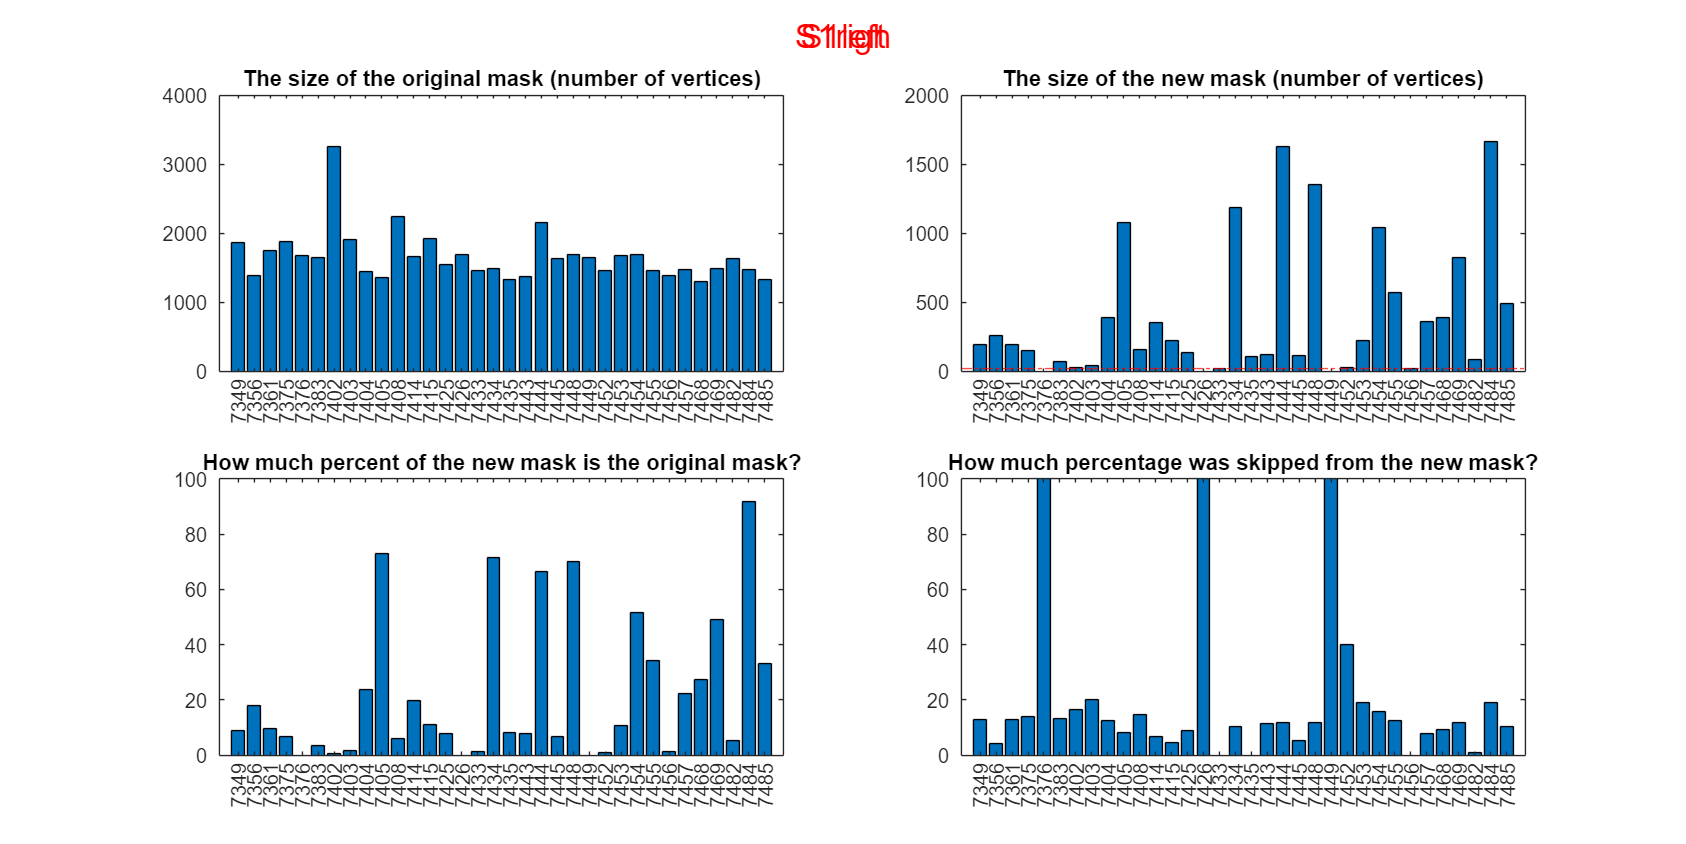

[~,~,percentoforiginalmask,~,~]=plotroi('S1','righ');

mean(percentoforiginalmask)

ans = 22.1071

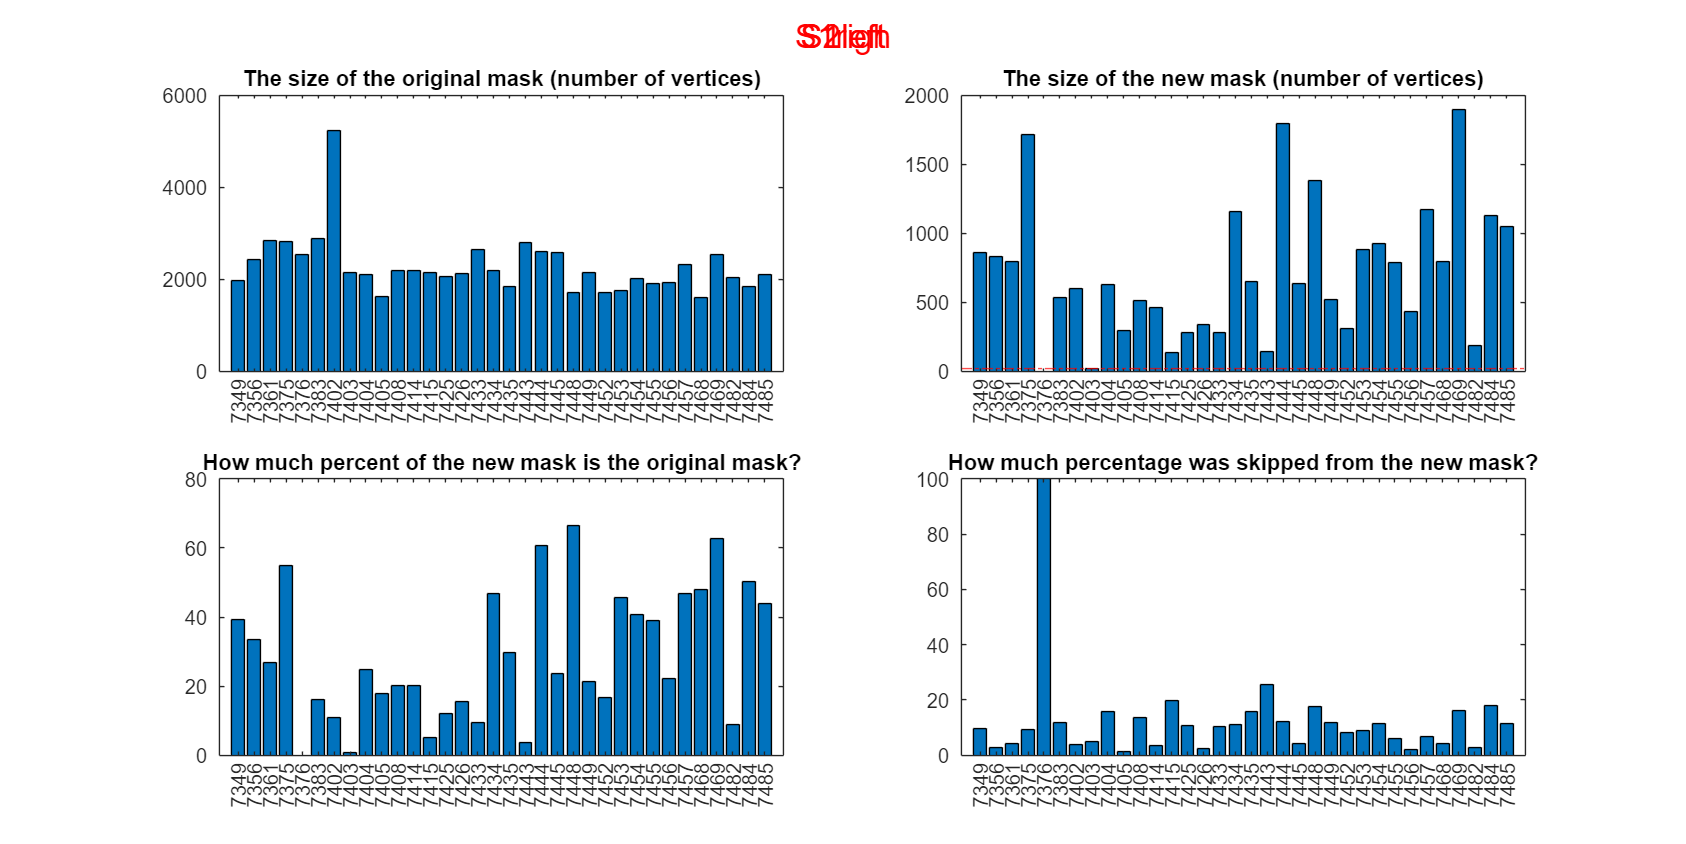

[~,~,percentoforiginalmask,~,~]=plotroi('S2','left');

mean(percentoforiginalmask)

ans = 28.9756

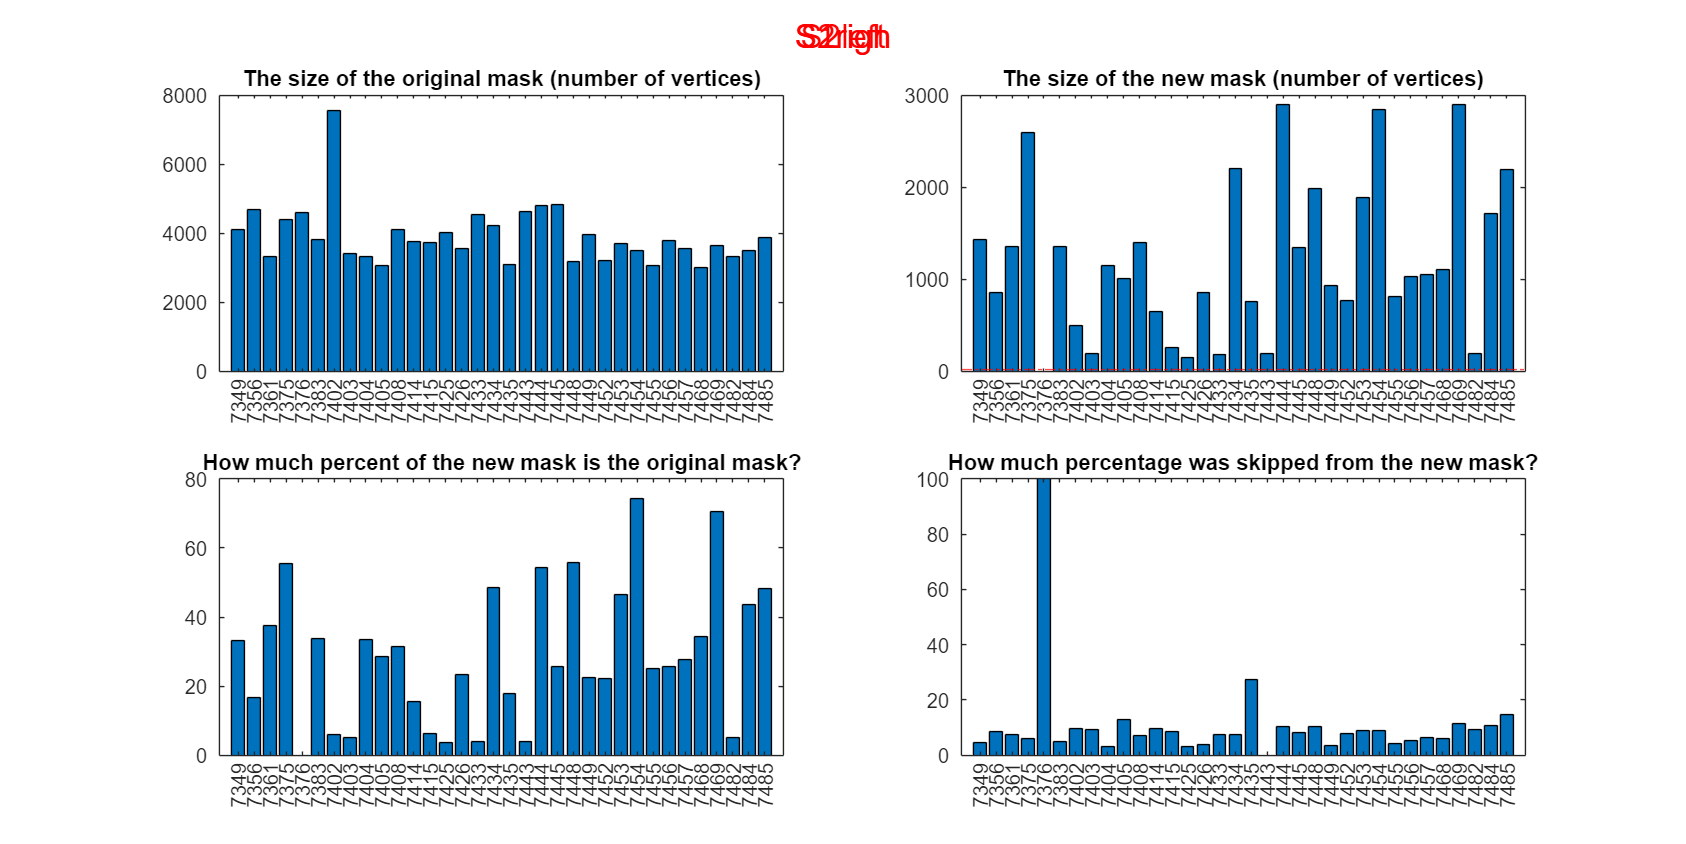

[~,~,percentoforiginalmask,~,~]=plotroi('S2','righ');

mean(percentoforiginalmask)

ans = 29.0056

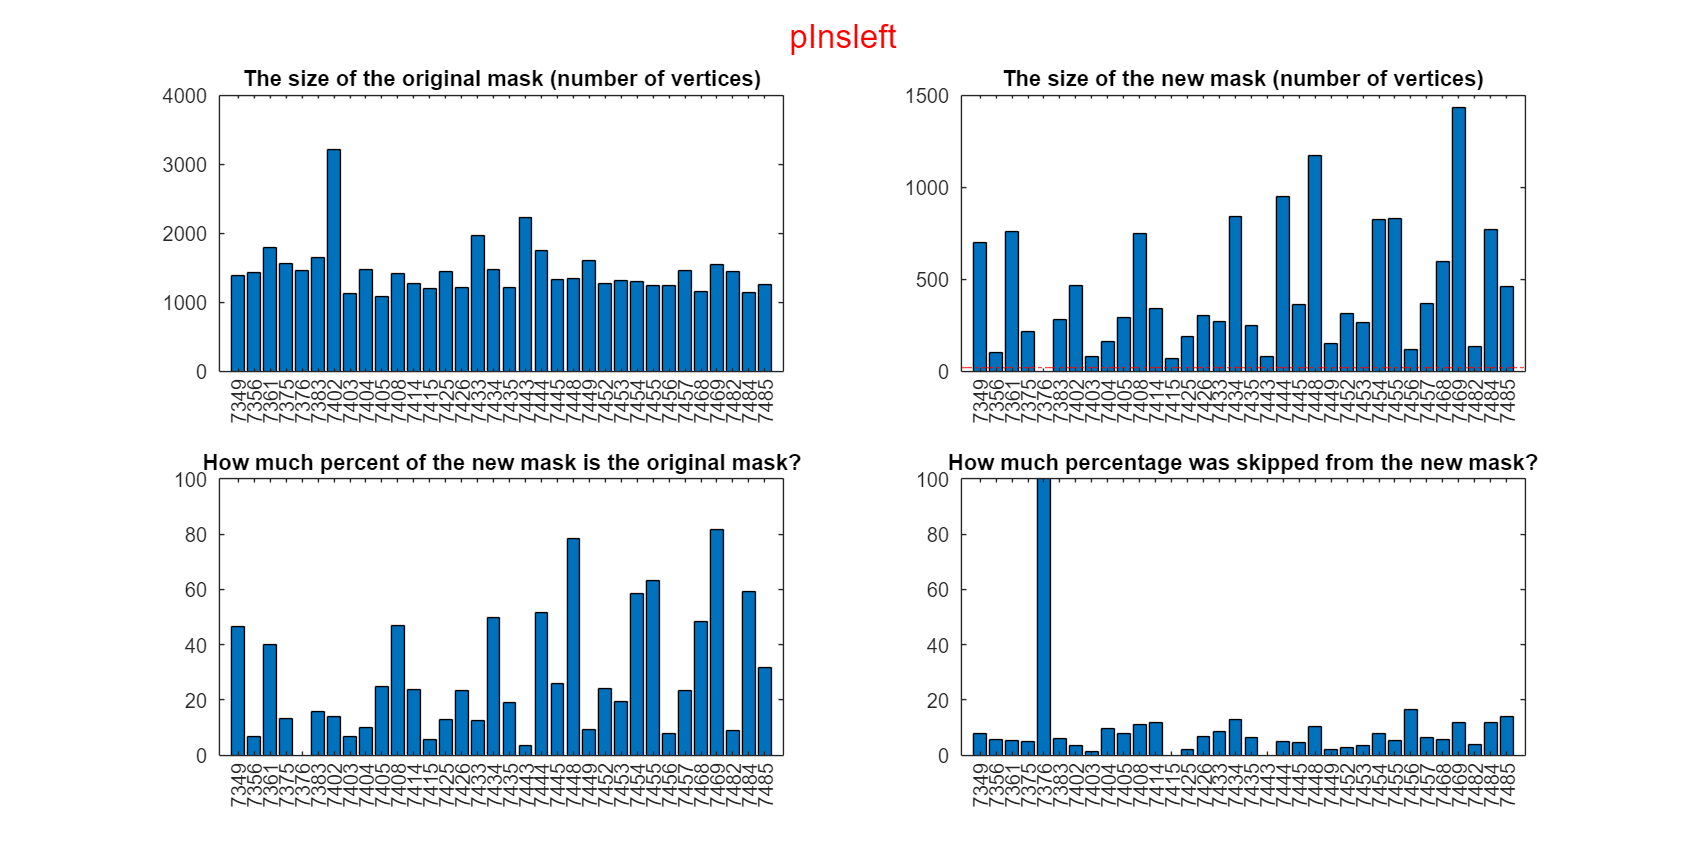

[~,~,percentoforiginalmask,~,~]=plotroi('pIns','left');

mean(percentoforiginalmask)

ans = 28.4659

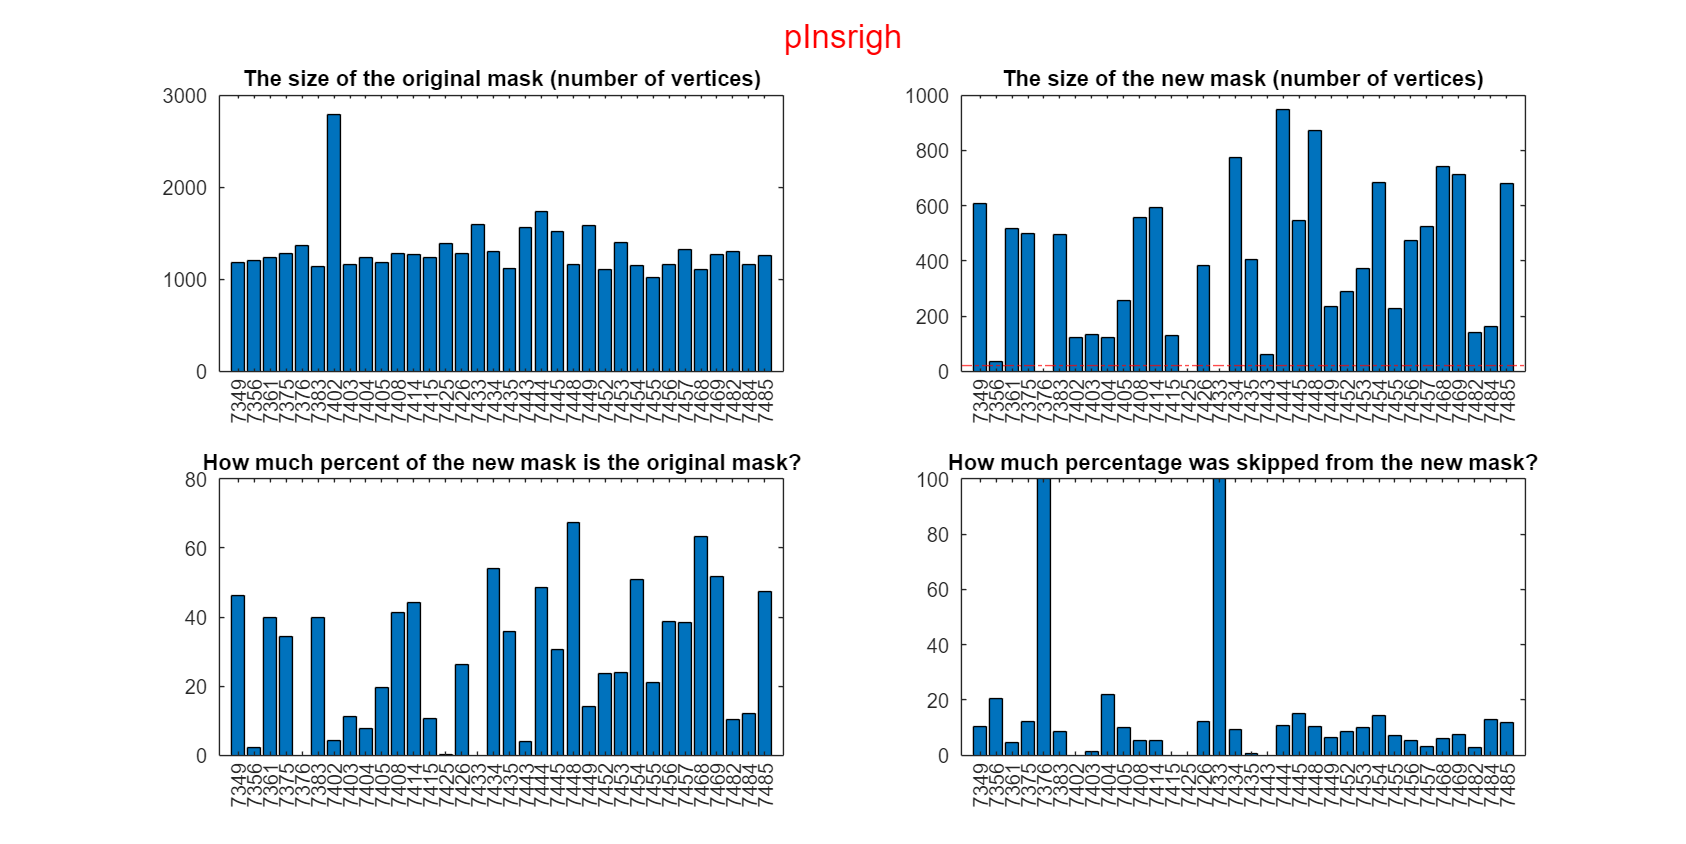


[~,~,percentoforiginalmask,~,~]=plotroi('pIns','righ');

mean(percentoforiginalmask)

ans = 28.3559

function [originalmasksize,newmasksize,percentoforiginalmask,percentofskippedverticesfromnew,mysubjesct]=plotroi(roi,side)
    allsubjid={7349, 7356, 7361, 7375, 7376,...
    7383, 7402, 7403, 7404,...
    7405, 7408, 7414, 7415,...
    7425, 7426, 7433, 7434,...
    7435, 7443, 7444, 7445,...
    7448, 7449, 7452, 7453,...
    7454, 7455, 7456, 7457,...
    7468, 7469, 7482, 7484, 7485};
    myidx=1;
    for subj=allsubjid
%         maki=load(['C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\' num2str(subj{1}) '\smootheddata\interimdata_smoothedmask.mat']);
        maki=load(['C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\' num2str(subj{1}) '\smootheddata\interimdata_smoothedmask_thr1.mat']);
        originalmasksize(myidx)=length(maki.interimdata_columns_smootheddata{1,1}.(roi).(side));
        intersectionofthetwomask(myidx)=sum(maki.interimdata_columns_smootheddata{1,1}.(roi).(side));
        newmasksize(myidx)=(maki.interimdata_columns_smootheddata{1,2}.(roi).(side));
        percentofskippedverticesfromnew(myidx)=round((newmasksize(myidx)-intersectionofthetwomask(myidx))/newmasksize(myidx)*100,2);
        percentoforiginalmask(myidx)=100-round((originalmasksize(myidx)-intersectionofthetwomask(myidx))/originalmasksize(myidx)*100,2);
        mysubjesct(myidx)=subj;
        myidx=myidx+1;
    end
    fig=figure('Position',[100, 100, 2400, 1200]);
    % --- Subplot 1: original mask size ---
    subplot(2,2,1)
    bar(originalmasksize)
    ax = gca;
    ax.XTick = 1:length(originalmasksize);
    ax.XTickLabel = allsubjid;
    ax.XTickLabelRotation = 90;  % same as xtickangle
    ax.FontSize = 12;
    ax.Title= text(0.5,0.5,'The size of the original mask (number of vertices)');
    
    % --- Subplot 2: new mask size ---
    subplot(2,2,2);
    bar(newmasksize)
    yline(20,'-.r');
    ax = gca;
    ax.XTick = 1:length(newmasksize);
    ax.XTickLabel = allsubjid;
    ax.XTickLabelRotation = 90;  % same as xtickangle
    ax.FontSize = 12;
    ax.Title= text(0.5,0.5,'The size of the new mask (number of vertices)');
    
    
    % --- Subplot 3: percent of the original mask ---
    subplot(2,2,3);
    
    bar(percentoforiginalmask)
    ax = gca;
    ax.XTick = 1:length(percentoforiginalmask);
    ax.XTickLabel = allsubjid;
    ax.XTickLabelRotation = 90;  % same as xtickangle
    ax.FontSize = 12;
    ax.Title= text(0.5,0.5,'How much percent of the new mask is the original mask?');
    % --- Subplot 4: percent of skipped vertices from the new mask ---
    subplot(2,2,4);
    
    percentofskippedverticesfromnew(isnan(percentofskippedverticesfromnew)) = 100;
    bar(percentofskippedverticesfromnew)
    ax = gca;
    ax.XTick = 1:length(percentofskippedverticesfromnew);
    ax.XTickLabel = allsubjid;
    ax.XTickLabelRotation = 90;  % same as xtickangle
    ax.FontSize = 12;
    ax.Title=text(0.5,0.5,'How much percentage was skipped from the new mask?');
    sgt = sgtitle([roi side],'Color','red');
    sgt.FontSize = 20;
        
%     clf(fig);
end
% originalmasksize=length(maki.interimdata_columns_smootheddata{1,1}.S1.left);
% intersectedmaskedsize=sum(maki.interimdata_columns_smootheddata{1,1}.S1.left);
% newmasksize=(maki.interimdata_columns_smootheddata{1,2}.S1.left)